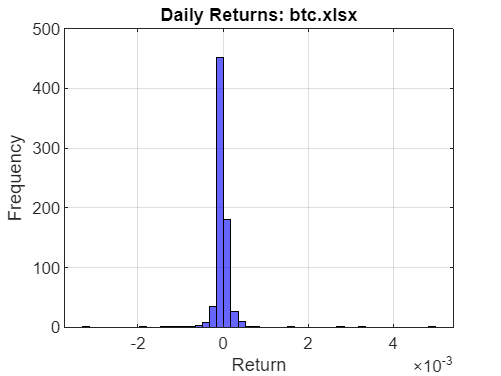

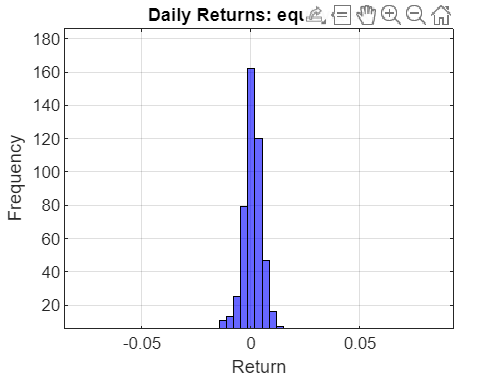

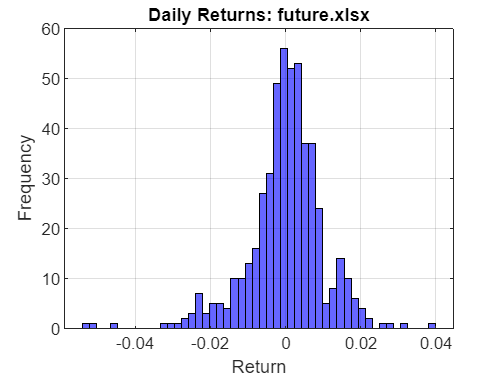

% __topic__ = Midterm paper
% __authors__ = Paul Seifert
% __course__ = Risk Managment
% __sup__ = Roptos
% __matlab version__ = R2024b

% Load data
fileList = {'btc.xlsx', 'equity.xlsx', 'future.xlsx'};
numFiles = length(fileList);

% 2. Pre-allocate a cell array to hold your tables
allData = cell(1, numFiles);

% Convert Excel-Files into  Tables
for k = 1:numFiles
    T = readtable(fileList{k});
    allData{k} = T;
end

% A)
% Calculate daily returns
for k = 1:numFiles
    T = allData{k};
    dailyReturn = (T.Open(2:end) - T.Close(1:end-1)) ./ T.Close(1:end-1); 
    T.dailyReturn = [NaN; dailyReturn]; % Puffer first day
    allData{k} = T;
end

% Plot daily returns
for k = 1:numFiles
    figure('Name', ['Dataset ' num2str(k)]);
    T = allData{k};
    histogram(T.dailyReturn, 50, 'FaceColor', 'blue');
    grid on;
    title(['Daily Returns: ', fileList{k}]);
    xlabel('Return');
    ylabel('Frequency');
end